# Laboratório de Instrumentação Industrial

## *Relatório 01 - Aulas Práticas 3, 4, 5 e 6*

#### Nome(s) Completo(s): 

Prezados(as) estudantes,

O MATLAB LIVE EDITOR é uma ferramenta interativa do MATLAB que combina código, saídas de execução, figuras e texto em um único documento.

Para elaborar este relatório, siga atentamente as orientações abaixo, implementando os trechos de código para calcular o que se pede.

O relatório será avaliado em cima do que for compreendido pelo professor, portanto, garanta que as funções e comandos utilizados estejam claros e muito bem comentados (%). Para isso:

- Dê **nomes intuitivos** para suas variáveis, bem como coloque um comentário descritivo sobre cada uma;

- **Comente o seu código** sempre que necessário, visto que ele será corrigido como uma memória de cálculo;

- Dê **título** para os gráficos, **nome** para os eixos e **legenda** para as curvas plotadas;

- Responda as **análises e comentários solicitados** em forma de comentário após o trecho de código ou em uma nova seção de texto.

Ao finalizar, você deve gerar um PDF (use o ícone `Export `$\longrightarrow$ `Export to PDF...`) e submeta-o juntamente com este arquivo `.mlx` na tarefa disponibilizada no Moodle.

**Introdução**

    A calibração é uma forma de realizar a comparação dos valores de medição

de um instrumento que possui erros conhecidos (chamado de instrumento padrão)

com um instrumento que está em teste. Ela é essencial para que o processo conte

com a maior precisão no momento da detecção de diversas grandezas. Assim,

sendo de grande importância na indústria, pois possibilita avaliar a confiabilidade

dos valores indicados pelos instrumentos, visando manter a qualidade da produção.

Dessa forma, o objetivo das práticas seguintes é calibrar e avaliar a medição dos

sensores em questão.

## Aula Prática 03

**Equipamentos e softwares utilizados**

    Os equipamentos utilizados para a prática de número três foram o Módulo de

Instrumentação, Controle e Automação (MICA), um miliamperímetro alicate para

processos Fluke 773. Já os softwares utilizados foram o Softwares RSLogix 5000

e o SCADA Intouch.

Após realizar os Procedimentos Experimentais de 1 a 11 da Aula Prática 03, resolva os procedimentos a seguir:

**Preparação para os Procedimentos 12 a 14:**

Registre, em ordem crescente, os pontos de corrente indicados pelo Padrão de Medição utilizado, pela Interface SCADA (IHM) e os valores numéricos da conversão A/D do cartão analógico do MICA.

% Padrão (mA): [ <valores> ]
Padrao_3 = [ 4, 6.42, 8, 9.39, 12, 16, 20 ];
% IHM (mA): [ <valores> ]
IHM_3 = [ 3.99, 6.4, 7.98, 9.37, 11.97, 15.97, 19.96];
% Cartão: [ <valores> ]
Cartao_3 = [-29858, -20985, -15168, -10051, -00479, 14248, 28937];


Determine a equação que relaciona os valores *C* do cartão analógico com os valores *I* de corrente, considerando as faixas $\left\lbrack 3\ldotp 2,21\ldotp 0\right\rbrack \;\left(\textrm{mA}\right)\leftrightarrow \left\lbrack -32766,32766\right\rbrack$.

%Por ser uma relação linear equação é do tipo C = a*I + b que caracteriza a equação de uma reta,
I = [3.2, 21];
C = [-32766, 32766];
%O coeficiente 'a'equeivale ao coeficiente de angulação da reta e pode ser calculada por:
% a = ΔC/ΔI
a = (C(2) - C(1))/(I(2) - I(1))

a = 3.6816e+03

%Para descobrir o valor do coeficiente linear (b), usa-se o valor do coeficiente angular (a) 
% encontrado e um dos pares de pontos, nesse caso, usaremos (21, 32766),
%subtituindo os valores na fórmula y = ax + b, temos:
b = C(2) - a*I(2)

b = -4.4547e+04

Para cada ponto obtido na Aula Prática 03, calcule o valor da conversão A/D realizada pelo cartão analógico.

C = a*IHM_3 + b

C = 1.0e+04 *

   -2.9858   -2.0985   -1.5168   -1.0051   -0.0479    1.4248    2.8937


Consulte o manual do padrão de medição utilizado na prática (disponível no Moodle) e indique qual a incerteza apresentada.

Consultando o manual do cartão analógico do MICA, foi encontrado uma

incerteza de +/- 0,2% do fundo de escala, que corresponde a 21 mA. Dessa forma, o

instrumento a ser calibrado possuirá erro em suas medições de:

U_MICA = 0.002*21

U_MICA = 0.0420

%No miliamperímetro Fluke, foi encontrada uma incerteza com resolução de 0,01 mA e erro de 0,2% + 2 dígitos
% para a fonte de corrente. Logo, a incerteza será de 0,2% do valor medido, somado de 0,02 mA.
U_Fluk = Padrao_3*0.002 + 0.02

U_Fluk =     0.0280    0.0328    0.0360    0.0388    0.0440    0.0520    0.0600


**Procedimentos 12 a 14:**

12) Considerando todos os pontos de medição de corrente realizados, expresse o resultado de medição para cada indicação, separadamente, baseando-se apenas nas informações contidas no manual do fabricante. *Em outras palavras, para cada ponto obtido, expresse o resultado da medição considerando, apenas, a incerteza apresentada no item anterior.*

UIHM_3 = [IHM_3.' - U_MICA, IHM_3.', IHM_3.' + U_MICA];
UIHM_3.'

ans =     3.9480    6.3580    7.9380    9.3280   11.9280   15.9280   19.9180
    3.9900    6.4000    7.9800    9.3700   11.9700   15.9700   19.9600
    4.0320    6.4420    8.0220    9.4120   12.0120   16.0120   20.0020


%3.990 +- 0.042
%6.400 +- 0.042
%7.980 +- 0.042
%9.370 +- 0.042
%11.970 +- 0.042
%15.970 +- 0.042
%19.960 +- 0.042

13) Plote os pontos do amperímetro utilizado expressando o intervalo de incertezas para cada um, obtido no item anterior, *i.e.*, os 3 pontos dos procedimentos de 5 a 9 mais os demais pontos propostos pelo professor (**ATENÇÃO:** algumas bancadas coletaram mais de 3 pontos utilizando o Fluke 773). Cada ponto deve conter os seus intervalos de incerteza expressos, conforme obtido no item anterior.

- **DICA: **utilize o comando `boxplot(X,’plotstyle’,’compact’,’labels’,{x1 x2 ... xN})`, onde X é a matriz com os N pontos de medição coletados durante a aula com os seus respectiovos intervalos de incerteza:

            
$$X=\left\lbrack \begin{array}{cccc}
x_1 -U_1  & x_2 -U_2  & \cdots  & x_N -U_N \\
x_1  & x_2  & \cdots  & x_N \\
x_1 +U_1  & x_2 +U_2  & \cdots  & x_1 +U_N 
\end{array}\right\rbrack$$


- **OBSERVAÇÃO: **Utilize a ferramenta de zoom para melhorar a visualização dos pontos.

boxplot(UIHM_3.', 'plotstyle', 'compact', 'label',{'x1', 'x2', 'x3', 'x4', 'x5', 'x6', 'x7'})

'boxplot' requires one of the following:
  SimBiology
  Statistics and Machine Learning Toolbox

14) Estime uma reta de calibração para o experimento (Indicações IHM x Indicações Amperímetro), utilizando o algoritmo de Mínimos Quadrados. Apresente os valores da sensibilidade e do erro sistemático.

plot

14.1) Plote a reta de calibração estimada. 

**ATENÇÃO:** O gráfico da reta de calibração deve estar sobreposto aos pontos coletados (marcados com um círculo - "o").

14.2) Verifique e comente, de forma quantitativa, se as indicações mostradas pela IHM (Intouch) estão adequadas, tendo como referência a incerteza do amperímetro utilizado.

## Aula Prática 04

Após realizar os Procedimentos Experimentais de 1 a 10 da Aula Prática 04, resolva os procedimentos a seguir:

**Preparação para os Procedimentos 11 a 18:**

Registre, em ordem crescente, os pontos de pressão e de corrente indicados pelo Padrão de Medição utilizado e pela Interface SCADA (IHM).

% Padrão (kPa): [ <valores> ]
% IHM (kPa): [ <valores> ]
% Padrão (mA): [ <valores> ]
% IHM (mA): [ <valores> ]



11) Utilizando o algoritmo de Mínimos Quadrados e com os pontos coletados, realize o ajuste da **reta de calibração** (Indicações do Padrão x Indicações da IHM) para o experimento de calibração realizado com o sistema de medição. 

11.1) Plote a reta de calibração estimada. O gráfico da reta de calibração deve estar sobreposto ao pontos coletados (marcados com um círculo - "o").

12) Baseando-se nos dados do experimento, calcule e expresse o erro sistemático desse sistema de medição, bem como a sua sensibilidade.

13) Levando em consideração a combinação das incertezas. 

13.1) Qual a **incerteza padrão** devido ao erro de estimação dos parâmetros *a* e *b* da reta de calibração?

13.2) Qual a **incerteza padrão** do manômetro padrão do calibrador Fluke 718?

13.3) Qual a **incerteza padrão** do cartão analógico do CLP em kPa?

13.4) Considerando as incertezas calculadas anteriormente, calcule a incerteza expandida da indicação não-corrigida ($y$) do instrumento, para um intervalo de confiança de 95% (para $v\longrightarrow \infty ,t\longrightarrow 1,960$).

- **DICA:** siga o Roteiro 1 (disponível no moodle). Entenda que é necessário calcular a incerteza padrão combinada e um vetor de graus de liberdade efetivo, bem como outro vetor de coeficientes t-Student.

14) Baseando-se no vetor de incertezas expandidas calculado, indique e justifique qual é o melhor erro a ser expresso: máximo, mínimo, médio ou mediano?

14.1) Expresse esse erro em sua forma fiducial ao sistema de medição (em % do F.E.).

15) Após a calibração desse sistema de medição, diante da incerteza expandida calculada no item 13, expresse o **resultado de medição** para as indicações (não-corrigidas) referentes às medidas 1, 4, 7 e 9. **Comente os resultados obtidos**. 

- **OBSERVAÇÃO:** não se esqueça de considerar a **correção** do sistema de medição.

16) Plote novamente a reta de calibração sobreposta aos pontos coletados, acrescida da **região 01** de incertezas **sem o fator de expansão**,* i.e*., apenas a incerteza padrão combinada, bem como acrescida da **região 02** de incertezas **com o fator de expansão**,* i.e*., o *t-student *encontrado para 95% (região do intervalo de confiança calculado). 

16.1) Você observa algum ponto coletado fora da **região 01**? E fora da **região 02**? **Comente os resultados obtidos**. 

17) Calcule a *linearidade *do sistema de medição, para o experimento de calibração realizado. **Comente os resultados obtidos.**

18) Como obter a** indicação corrigida** para esse sistema de medição? A incerteza de medição (intervalos de confiança) podem ser os mesmos obtidos no item 13? **Justifique utilizando cálculos e demonstrações.**

## Aula Prática 05

Após realizar os Procedimentos Experimentais de 1 a 10 da Aula Prática 05, resolva os procedimentos a seguir:

**Preparação para os Procedimentos 11 a 19:**

Registre, em ordem crescente, os pontos de pressão e de corrente indicados pelo Padrão de Medição utilizado e pela Interface SCADA (IHM).

% Padrão (°C): [ <valores> ]
PADRAO_5 = [ 80.00, 70.00, 60.00, 50.00, 40.00, 30.00, 20.00, 10.00];
% IHM (°C): [ <valores> ]
IHM_5 = [ 79.99, 70.99, 61.03, 49.28, 40.38, 31.09, 20.02, 7.12];
% IHM (mA): [ <valores> ]
IHM_5_mA = [ 19.99, 18.19, 16.206, 13.86, 12.17, 10.22, 8.03, 5.42];

11) Utilizando o algoritmo de Mínimos Quadrados e com os pontos coletados, realize o ajuste da **reta de calibração** (Indicações do Padrão x Indicações da IHM) para o experimento de calibração realizado com o sistema de medição. 

% Ajuste da curva usando mínimos quadrados
grau = 1; % Grau do polinômio ajustado
p = polyfit(PADRAO_5,IHM_5_mA,grau); % Coeficientes do polinômio ajustado

11.1) Plote a reta de calibração estimada. O gráfico da reta de calibração deve estar sobreposto ao pontos coletados (marcados com um círculo - "o").

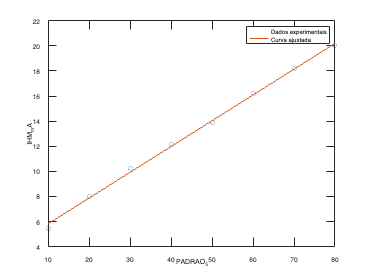

% Plot dos dados e da curva ajustada
plot(PADRAO_5,IHM_5_mA,'o',PADRAO_5,polyval(p,PADRAO_5),'-')
legend('Dados experimentais','Curva ajustada')
xlabel('PADRAO_5')
ylabel('IHM_5_mA')

12) Baseando-se nos dados do experimento, calcule e expresse o erro sistemático desse sistema de medição, bem como a sua sensibilidade.

% Cálculo do erro sistemático
residuos = IHM_5_mA - polyval(p, PADRAO_5);
erro_sistematico = mean(residuos);
% Cálculo da sensibilidade
sensibilidade = abs(p(1));
% Display dos valores
disp(['O valor do erro sistemático é ', num2str(erro_sistematico)]);

O valor do erro sistemático é -3.8858e-15


disp(['O valor da sensibilidade é ', num2str(sensibilidade)]);

O valor da sensibilidade é 0.20528


13) Obtenha a **indicação corrigida** para esse sistema de medição.

% Correção da indicação
indicacao_corrigida = PADRAO_5 + erro_sistematico;
% Display dos valores
disp(['A indicação corrigida do sistema de medição é de ', num2str(indicacao_corrigida), ' mA.']);

A indicação corrigida do sistema de medição é de 80           70           60           50           40           30           20           10 mA.


14) Levando em consideração a combinação das incertezas. 

14.1) Qual a **incerteza padrão** devido ao erro de estimação dos parâmetros *a* e *b* da reta de calibração?

% Matriz de covariância para calcular a incerteza padrão dos coeficientes da reta
covariance_matrix = inv(PADRAO_5'*PADRAO_5)*sum(residuos.^2)/(length(PADRAO_5)-2); % Matriz de covariância

% Incerteza padrão do coeficiente a
incerteza_a = sqrt(covariance_matrix(1,1));
% Incerteza padrão do coeficiente b
incerteza_b = sqrt(covariance_matrix(2,2));
% Display dos valores
disp(['A incerteza padrão do coeficiente a é de ', num2str(incerteza_a), ' mA.']);

A incerteza padrão do coeficiente a é de Inf mA.


disp(['A incerteza padrão do coeficiente b é de ', num2str(incerteza_b), ' mA.']);

A incerteza padrão do coeficiente b é de Inf mA.


14.2) Qual a **incerteza padrão** do termômetro padrão Fluke 51/52 II?

%Para a faixa de medição de -50 °C a 1000 °C é de ±(0,05% da leitura + 0,3°C)

14.3) Qual a incerteza do cartão analógico do CLP em °C?

A incerteza padrão do coeficiente a é de Inf mA.


A incerteza padrão do coeficiente b é de Inf mA.


14.4) Considerando as incertezas calculadas anteriormente, calcule a incerteza expandida da indicação não-corrigida ($\hat{x}$) do instrumento, para um intervalo de confiança de 95% (para $v\longrightarrow \infty ,t\longrightarrow 1,960$).

- **DICA:** siga o Roteiro 1 (disponível no moodle). Entenda que é necessário calcular a incerteza padrão combinada e um vetor de graus de liberdade efetivo, bem como outro vetor de coeficientes t-Student.

15) Baseando-se no vetor de incertezas expandidas calculado, expresse o** erro **em sua forma** fiducial **ao sistema de medição (em % do F.E.).

16) Após a calibração desse sistema de medição, diante da incerteza expandida calculada no item 14, expresse o **resultado de medição** para as indicações (**corrigidas**) referentes às medidas 1, 3, 5 e 8. Não se esqueça de considerar correção do sistema de medição. **Comente os resultados obtidos**.

- **OBSERVAÇÃO:** não se esqueça de considerar correção do sistema de medição.

17) Plote novamente a reta de calibração sobreposta aos pontos coletados, acrescida da **região 01** de incertezas **sem o fator de expansão**,* i.e*., apenas a incerteza padrão combinada, bem como acrescida da **região 02** de incertezas **com o fator de expansão**,* i.e*., o *t-student *encontrado para **95%** (região do intervalo de confiança calculado).

17.1) Você observa algum ponto coletado fora da** região 01**? E fora da **região 02**? Comente os resultados obtidos.

18) Calcule a *linearidade *do sistema de medição para o experimento de calibração realizado. **Comente os resultados obtidos.**

19) A incerteza do sistema de medição seria afetada caso o sensor utilizado fosse um PT2000? Por quê? **Discuta demonstrando com cálculos.**

## Aula Prática 06

Após realizar os Procedimentos Experimentais de 1 a 7 da Aula Prática 06, resolva os procedimentos a seguir:

**Preparação para os Procedimentos 8 a 17:**

Registre, em ordem crescente, os pontos de pressão e de corrente indicados pelo Padrão de Medição utilizado e pela Interface SCADA (IHM).

% Padrão (g): [ <valores> ]

% IHM (g): [ <valores> ]
% IHM (mA): [ <valores> ]

8) Utilizando o algoritmo de Mínimos Quadrados e com os pontos coletados, realize o ajuste da **reta de calibração** (Indicações do Padrão x Indicações da IHM) para o experimento de calibração realizado com o sistema de medição.

8.1) Plote a reta de calibração estimada. O gráfico da reta de calibração deve estar sobreposto ao pontos coletados (marcados com um círculo - "o").

9) Baseando-se nos dados do experimento, calcule e expresse o erro sistemático desse sistema de medição, bem como a sua sensibilidade.

10) Obtenha a **indicação corrigida** para esse sistema de medição.

11) Levando em consideração a combinação das incertezas. 

11.1) Qual a **incerteza padrão** devido ao erro de estimação dos parâmetros *a* e *b* da reta de calibração?

11.2) Qual a **incerteza padrão** do Conjunto de Pesos Padrão (assuma o pior caso)?

11.3) Qual a incerteza do cartão analógico do CLP em g?

11.4) Considerando as incertezas calculadas anteriormente, calcule a incerteza expandida da indicação corrigida ($\hat{x}$) do instrumento, para um intervalo de confiança de 95% (para $v\longrightarrow \infty ,t\longrightarrow 1,960$).

- DICA: siga o Roteiro 1 (disponível no moodle). Entenda que é necessário calcular um vetor de graus de liberdade efetivo, bem como outro vetor de coeficientes t-Student.

12) Baseando-se no vetor de incertezas expandidas calculado, expresse o** erro **em sua forma** fiducial **ao sistema de medição (em % do F.E.)

13) Após a calibração desse sistema de medição, diante da incerteza expandida calculada no item 11, expresse o **resultado de medição **para as **indicações corrigidas** referentes as Medidas 200g, 1.000g, 2.500g e 5.000g. **Comente os resultados obtidos**.

- **OBSERVAÇÃO:** não se esqueça de considerar correção do sistema de medição.

14) Plote novamente a reta de calibração sobreposta aos pontos coletados, acrescida da **região 01** de incertezas **sem o fator de expansão**,* i.e*., apenas a incerteza padrão combinada, bem como acrescida da **região 02** de incertezas **com o fator de expansão**,* i.e*., o *t-student *encontrado para **95%** (região do intervalo de confiança calculado).

15) Você observa algum ponto coletado fora da** região 01**? E fora da **região 02**? **Comente os resultados obtidos.**

16) Calcule a *linearidade *do sistema de medição, para o experimento de calibração realizado.  

17) A célula de carga *SP4MAC3/5KG-1* da HBM, utilizada na balança, possui sensibilidade 2 mV/V, *i.e.*, para uma tensão de excitação de 5 V, ela terá um SPAN de 10 mV para a saída, *i.e.*, em 5 kg $\longrightarrow$ 10 mV). Dessa forma, observando o circuito condicionador de sinais da Figura 6.6 do roteiro, calcule a variação de tensão máxima que esta célula de carga fornece para a excitação a qual ela foi submetida.

18) Sob excitação adequada, a menor tensão possível gerada pela célula de carga SP4MAC3/5KG-1 ocorre para o peso de 1g. Logo, pesos menores que 1 g não são “detectados” pela balança. Ainda assim, não é possível realizar medições mesmo maiores que 5 g, por quê? **Discuta sugerindo melhorias nesse sistema de medição.** 

## Análise de Resultados 

Compare as procedimentos de calibração realizados nas Aulas Práticas 3, 4, 5 e 6. Quais as principais diferenças entre eles? Quais possuem padrões de medição variáveis e/ou invariáveis? Qual é o impacto de um padrão variável/invariável para o experimento de calibração?

Compare as** linearidades **dos sistemas de medição das Aulas Práticas 3, 4, 5 e 6.** Comente. **

Compare os **erros fiduciais** dos sistemas de medição das Aulas Práticas 3, 4, 5 e 6.** Comente.**

O método de cálculo de incertezas utilizado leva em consideração a repetição do experimento de calibração, *i.e.*, $m\ge 1$. Explique o porquê de se utilizar este método? Supondo uma variabilidade normal do experiemento, caso $m\gg 1$ (*i.e.*, $m$ grande), comente o que ocorrerá com o erro de medição?

## Conclusões

Não existe relatório sem conclusão! Seja pragmático e objetivo. Conclua sobre os resultados obtidos, a dificuldades encontradas e as decisões tomadas.  